# DTU 62743 Digital Signal Processing - EXAM_E25

**Student Name:** Mads Rudolph

**Student ID:** s246132

**Exam Date:** December 12, 2025

clear; close all; clc;

addpath('C:\Users\Mads2\DTU\3.semester\DSP\Helpers\');

fprintf('╔════════════════════════════════════════╗\n');
fprintf('║  DTU 62743 DSP Exam - December 2025  ║\n');
fprintf('╚════════════════════════════════════════╝\n\n');
fprintf('Date: %s\n', datestr(now, 'yyyy-mm-dd HH:MM'));

% Set publication-quality defaults for all figures
set(groot, 'defaultFigurePosition', [100 100 900 600]);
set(groot, 'defaultLineLineWidth', 1.5);
set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultAxesGridLineStyle', ':');
set(groot, 'defaultAxesGridAlpha', 0.3);

## Opgave 1 (40%)

##     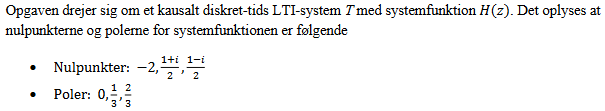

fprintf('\n╔═══════════════════════════════════════╗\n');
fprintf('║          PROBLEM 1 (XX%%)             ║\n');
fprintf('╚═══════════════════════════════════════╝\n\n');

## Problem 1-1:

**Skitser systemets pol- nulpunkts-diagram. Brug gerne MATLAB til at plotte diagrammet.**

fprintf('─── Problem 1-1 ───\n');

─── Problem 1-1 ───





% Define pole and zeros
zeros_H4 = [-2, ((1+1j)/2), ((1-1j)/2)]

zeros_H4 =   -2.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 - 0.5000i


poles_H4 = [0, 1/3, 2/3]

poles_H4 =          0    0.3333    0.6667



% Display
fprintf('\nZeros:\n');


Zeros:


disp(zeros_H4);

  -2.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 - 0.5000i



fprintf('Zeros magnitudes: ');

Zeros magnitudes: 

disp(abs(zeros_H4)');

    2.0000
    0.7071
    0.7071




fprintf('\nPoles:\n');


Poles:


disp(poles_H4);

         0    0.3333    0.6667



fprintf('Pole magnitudes: ');

Pole magnitudes: 

disp(abs(poles_H4)');

         0
    0.3333
    0.6667



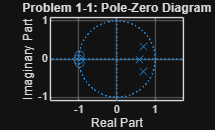


% Plot pole-zero diagram
figure;
zplane(B4, A4);
title('Problem 1-1: Pole-Zero Diagram');
grid on;

## Problem 1-2:

**Bestem systemfunktionen 𝐻(𝑧) samt konvergensområdet 𝑅𝑂𝐶(𝐻(𝑧)).**

fprintf('\n─── Problem 1-2 ───\n');



## Problem 1-3:

**Er systemet stabilt eller ustabilt? Begrund dit svar.**

fprintf('\n─── Problem 1-3 ───\n');


─── Problem 1-3 ───



% Stability check
fprintf('\n--- Stability ---\n');


--- Stability ---


if all(abs(poles_H4) < 1)
    fprintf('✓ STABLE (all |p| < 1)\n');
else
    fprintf('✗ NOT STABLE\n');
end

✓ STABLE (all |p| < 1)



fprintf('System is stable, all poles are strictly inside the unit circle\n');

System is stable, all poles are strictly inside the unit circle


## Problem 1-4: 

** dette spørgsmål kan følgende formel for Z-transformation frit benyttes. I formlen betegner 𝑢[𝑛] enhedstrinnet.**

Et diskret-tids signal er defineret ved

Bestem den Z-transformerede af signalet.

fprintf('\n─── Problem 1-4 ───\n');


─── Problem 1-4 ───



% h[n] = δ[n] + 2δ[n-1] + 6δ[n-2] + 2δ[n-3] + δ[n-4]
% 
% Taking Z-transform (using δ[n-k] → z^(-k)):
%   δ[n]   → 1
%   2δ[n-1] → 2z^(-1)
%   6δ[n-2] → 6z^(-2)
%   2δ[n-3] → 2z^(-3)
%   δ[n-4] → z^(-4) 

% Manual result:
fprintf('Result: H(z) = 1 + 2z^(-1) + 6z^(-2) + 2z^(-3) + z^(-4)\n\n');


## Problem 1-5:

**Signalet 𝑥1[𝑛] bruges som inputsignal til det ovenstående system T. Bestem den Z-transformerede 𝑌1(𝑧) af det tilhørende outputsignal 𝑦1[𝑛]. Svaret ønskes angivet på en form, der ikke kan forkortes.**

fprintf('\n─── Problem 1-5 ───\n');




## Problem 1-6:

**Beregn outputsignalet 𝑦1[𝑛].**

fprintf('\n─── Problem 1-6 ───\n');


─── Problem 1-6 ───



✓ Problem 1 Complete!


## Problem 1-7:

Spørgsmålet drejer sig om systemfunktionen 𝐻(𝑧). Bestem en systemfunktion for et minimum fase system 𝐻𝑚𝑝(𝑧) og en systemfunktion for et all-pass system 𝐻𝑎𝑝(𝑧) således at

Plot desuden magnituderesponset og faseresponset for 𝐻𝑎𝑝(𝑧) ved brug af MATLAB kommandoen freqz(). Ser magnituderesponset ud som forventet? 

fprintf('\n─── Problem 1-7 ───\n');


## PROBLEM 2 (30%)

**Et digital lavpas filter er givet på Direct form II ved følgende filter realisering:**

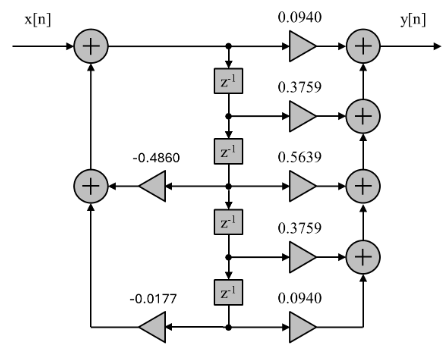

Filteret er designet til en samplingsfrekvens på Fs = 1600 Hz.

Filteret er et lavpas filter og har en dæmpning på 3 dB ved en frekvens på 400 Hz.

 spørgsmålene nedenfor er det tilladt at benytte Matlab. Koden til Matlab skal i så fald inkluderes i besvarelsen således at det dokumenteres hvorledes Matlab funktionerne benyttes.

fprintf('\n╔═══════════════════════════════════════╗\n');
fprintf('║          PROBLEM 2 (XX%%)             ║\n');
fprintf('╚═══════════════════════════════════════╝\n\n');

## Problem 2-1:

**• Opskriv overførelsesfunktionen (engelsk: transfer function) for filteret. **

**• Find og plot magnituden af frekvensresponset for lavpas filteret i dB som funktion af frekvens i Hz fra 0 Hz til Fs/2. (Hint: Matlab kommandoen freqz kan benyttes). **

**• Hvad er dæmpningen ved 400 Hz? Passer dette med ovenstående beskrivelse af filteret? **

**• Hvad er dæmpningen ved 600 Hz? (Hint: Det er tilstrækkeligt blot at aflæse på plottet). **

**• Plot fasen af frekvensresponset for filteret (engelsk: phase frequency reponse). **

**• Er fasen i pasbåndet for filteret lineært eller ikke-lineært? Baseret på filter typen er dette forventet? **

fprintf('─── Problem 2-1 ───\n');

─── Problem 2-1 ───



% Given filter koefficienter

% Numerator (feedforward path)
B2 = [0.0940, 0.3759, 0.5639, 0.3759, 0.0940];

% Denominator (feedback path)
A2 = [1, 0.4860, 0.0177];

Fs2 = 1600;     % Sampling frequency [Hz]
Ts2 = 1/Fs4;    % Sampling period [s]

% 1)

% Display transfer function
fprintf('(1) Transfer function H(z):\n');

(1) Transfer function H(z):


H4_sys = tf(B2, A2, Ts2, 'Variable', 'z^-1')


H4_sys =
 
  0.094 + 0.3759 z^-1 + 0.5639 z^-2 + 0.3759 z^-3 + 0.094 z^-4
  ------------------------------------------------------------
                  1 + 0.486 z^-1 + 0.0177 z^-2
 
Sample time: 0.0002 seconds
Discrete-time transfer function.


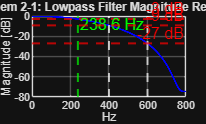



% 2)

% Frequency vector (0 to Nyquist)
F_vec = linspace(0, Fs2/2, 10000);  % Hz

% Compute frequency response
[H4, F4_resp] = freqz(B2, A2, F_vec, Fs2);

% % Shift freqz result to [-π, π]
% w_shift = F4_resp - pi;
% H_shift = fftshift(H4);

% Magnitude in dB
Mag4_dB = 20*log10(abs(H4));

% Plot
figure;
plot(F4_resp, Mag4_dB, 'b-', 'LineWidth', 1.5);
hold on;
grid on;
xlabel('Hz');
ylabel('Magnitude [dB]');
xlim([0 Fs2/2]);
title('Problem 2-1: Lowpass Filter Magnitude Response');


% Mark -3 dB line
yline(-3, '--r', '-3 dB', 'LineWidth', 1.5, 'FontSize', 12);

% Find -3 dB frequency
idx_3dB = find(Mag4_dB >= -3, 1, 'last');
F_3dB = F4_resp(idx_3dB);

% Mark the found frequency
xline(F_3dB, '--g', sprintf('%.1f Hz', F_3dB), ...
      'LineWidth', 1.5, 'FontSize', 12, 'LabelOrientation', 'horizontal');
xline(400, '--w', 'LineWidth', 1.5, 'FontSize', 12);
xline(600, '--w', 'LineWidth', 1.5, 'FontSize', 12);

yline(-9.2, '--r', '-9 dB', 'LineWidth', 1.5, 'FontSize', 12);
yline(-27, '--r', '-27 dB', 'LineWidth', 1.5, 'FontSize', 12);
hold off;



% 3)

fprintf('Damping at different frequencies\n');

Damping at different frequencies


fprintf('Damping at 238 Hz: -3 dB\n');

Damping at 238 Hz: -3 dB


fprintf('Damping at 400 Hz: -9 dB (Doesnt match filter description)\n');

Damping at 400 Hz: -9 dB (Doesnt match filter description)


fprintf('Damping at 600 Hz: -27 dB\n');

Damping at 600 Hz: -27 dB


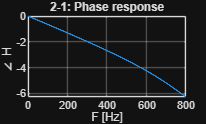





% Phase response
figure;
plot(F4_resp, unwrap(angle(H4)), 'LineWidth', 1.2); grid on; hold on;
xlabel('F [Hz]');
ylabel('\angle H ');
title('2-1: Phase response');

% 6)

fprintf('The Phase response is not linear as seen on the graph, and it shouldnt because Direct II doesnt have linear phase\n');

The Phase response is not linear as seen on the graph, and it shouldnt because Direct II doesnt have linear phase


## Problem 2-2:

**• Plot pol- og nul-punktsdiagrammet for filteret (Hint: Matlab kommandoen zplane kan benyttes). **

**• Er filteret stabilt? Begrund dit svar. **

**• Plot impulsresponset for filteret som funktion af sample nummer, n, fra -10 til 30. (Hint: Matlab kommandoen filter kan anvendes med passende input).**

fprintf('\n─── Problem 2-2 ───\n');


─── Problem 2-2 ───


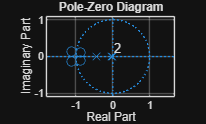


% H4(z) pole-zero plot
figure;
zplane(B2, A2);
title('Pole-Zero Diagram');
grid on;


fprintf('Since the zeros are outside of the ROC its not stable, as seen on the pole-zero plot \n');

Since the zeros are outside of the ROC its not stable, as seen on the pole-zero plot 



n = -10:30;

H4_filtered = filter(B2, A2, n) 

H4_filtered =    -0.9400   -4.1482   -7.7415   -8.6635   -7.6821   -6.6391   -5.6596   -4.6504   -3.6545   -2.6527   -1.6535   -0.6531    0.3467    1.3468    2.3467    3.3467    4.3467    5.3467    6.3467    7.3467    8.3467    9.3467   10.3467   11.3467   12.3467   13.3467   14.3467   15.3467   16.3467   17.3467   18.3467   19.3467   20.3467   21.3467   22.3467   23.3467   24.3467   25.3467   26.3467   27.3467   28.3467


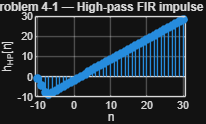


figure;
stem(n, H4_filtered, 'filled'); grid on;
xlabel('n');
ylabel('H4');
title('impulse response');

## Problem 2-3: Magnitude Response & Cutoff Detection

**Et analogt signal er givet ved:**

**𝑋𝐴(𝑡) = 𝐴1 𝑐𝑜𝑠(2𝜋𝐹1𝑡) + 𝐴2 𝑐𝑜𝑠(2𝜋𝐹2𝑡) + 𝐴3 𝑐𝑜𝑠(2𝜋𝐹3𝑡)**

**hvor**

**• F1 = 100 Hz **

**• F2 = 300 Hz **

**• F3 = 600 Hz **

**• A1 = 1 **

**• A2 = 2 **

**• A3 = 3**

**Signal samples nu med følgende parameter:**

**• Sampling frekvens Fs = 1600 Hz **

**• Antal sampling punkter, N = 2^14.**

% Given analog signal: xa(t) = A1*cos(2π*F1*t) + A2*cos(2π*F2t) + A3*cos(2πF3*t)
A1 = 1;   F1 = 100;      % First component
A2 = 2;   F2 = 300;      % Second component
A3 = 3;   F3 = 600;      % Third component
Fs4 = 1600;              % Sampling frequency

% 1)• Baseret på sampling frekvensen, udregn den maksimale signalfrekvens, der kan samples uden at frekvens aliasering forekommer. 

% Check aliasing
F_Nyquist = Fs4/2;
fprintf('Nyquist frequency: %.0f Hz\n\n', F_Nyquist);

Nyquist frequency: 800 Hz




fprintf('Component 1: F1 = %.0f Hz\n', F1);

Component 1: F1 = 100 Hz


if F1 < F_Nyquist
    fprintf('  %.0f < %.0f → NO aliasing ✓\n\n', F1, F_Nyquist);
else
    fprintf('  %.0f >= %.0f → ALIASING! ⚠️\n\n', F1, F_Nyquist);
end

  100 < 800 → NO aliasing ✓




fprintf('Component 2: F2 = %.0f Hz\n', F2);

Component 2: F2 = 300 Hz


if F2 < F_Nyquist
    fprintf('  %.0f < %.0f → NO aliasing ✓\n\n', F2, F_Nyquist);
else
    fprintf('  %.0f >= %.0f → ALIASING! ⚠️\n\n', F2, F_Nyquist);
end

  300 < 800 → NO aliasing ✓




fprintf('Component 3: F3 = %.0f Hz\n', F3);

Component 3: F3 = 600 Hz


if F2 < F_Nyquist
    fprintf('  %.0f < %.0f → NO aliasing ✓\n\n', F3, F_Nyquist);
else
    fprintf('  %.0f >= %.0f → ALIASING! ⚠️\n\n', F3, F_Nyquist);
end

  600 < 800 → NO aliasing ✓




fprintf('The maximal sampling frequency is determined by the highest F wich is F3 so it needs to be over 600 Hz\n');

The maximal sampling frequency is determined by the highest F wich is F3 so it needs to be over 600 Hz



% 2)• Definer en diskret tidsvektor, som starter ved t = 0 sekunder. 
t = 0:1/Fs4:0.05;

% • Udregn det samplede signal x[n]. 

H4_sampled = A1*cos(2*pi*F1*t)+A2*cos(2*pi*F2*t)+A3*cos(2*pi*F3*t)

H4_sampled =     6.0000   -0.4321   -0.7071    0.6562   -3.0000    3.5864    0.7071   -3.8106         0   -3.8106    0.7071    3.5864   -3.0000    0.6562   -0.7071   -0.4321    6.0000   -0.4321   -0.7071    0.6562   -3.0000    3.5864    0.7071   -3.8106         0   -3.8106    0.7071    3.5864   -3.0000    0.6562   -0.7071   -0.4321    6.0000   -0.4321   -0.7071    0.6562   -3.0000    3.5864    0.7071   -3.8106         0   -3.8106    0.7071    3.5864   -3.0000    0.6562   -0.7071   -0.4321    6.0000   -0.4321


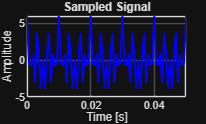



% 3)• Plot det samplede signal, x[n], i tidsintervallet fra 0 til 0.05 sekunder.

figure;
plot(t, H4_sampled, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('Amplitude');
title('Sampled Signal');
xlim([0 0.05]);

## Problem 2-4:

**• Udregn frekvensspektrummet af det samplede signal (Hint: Matlab kommandoen FFT kan benyttes). **

**• Plot frekvensspektrummet af det samplede signal med en korrekt skalering af y-aksen. **

**• Kommenter på om frekvenskomponenterne og amplituderne stemmer overens med det forventede. **

fprintf('\n─── Problem 2-4 ───\n');



## Problem 2-5: 

**Frekvenskomponenten ved 600 Hz ønskes nu dæmpet. Til dette formål anvendes det digitale filter, der blev introduceret i spørgsmål 2-1.**

**• Benyt filteret (fra spørgsmål 2-1) til at filtrere det samplede signal, x[n]. Dette skal gøres ved at benytte Matlab kommandoen filter. **

**• Udregn frekvensspektrummet af det filtrede signal. **

**• Plot frekvensspektrummet af det filtrede signal med en korrekt skalering af y-aksen. **

**• Find eller aflæs hvad amplituden af signalet er ved henholdsvis 100 Hz, 300 Hz, og 600 Hz. **

**• Bestem ud fra amplituderne hvor meget signalet ved 600 Hz blev dæmpet (angivet i dB). **

**• Kommenter på om denne dæmpning ved 600 Hz stemmer overens med den dæmpning der blev fundet ud fra magnituden af frekvensresponset for filteret, som blev adresseret i spørgsmål 2-1. **

fprintf('\n─── Problem 2-5 ───\n');



## PROBLEM 3 (30%)

**Opgaven omhandler design at højpas FIR filtre. I denne opgave skal et digitalt filter designes. Filteret er karakteriseret som følger: **

**• Filtertype: Højpas FIR filter. **

**• Filter design metode: Fourier transform metoden. **

**• Pasbånd frekvens, Fpass = 1750 Hz. **

**• Stopband frekvens, Fstop = 1250 Hz. **

**• Stopbånd dæmpning AsdB = 20 dB. **

**• Sampling frekvens, Fs = 5000 Hz. **

**I spørgsmålene nedenfor er det tilladt at benytte Matlab. Koden til Matlab skal i så fald inkluderes i besvarelsen således at det dokumenteres hvorledes Matlab funktionerne benyttes.**

fprintf('\n╔═══════════════════════════════════════╗\n');
fprintf('║          PROBLEM 3 (XX%%)             ║\n');
fprintf('╚═══════════════════════════════════════╝\n\n');

## Problem 3-1:

**• Vis at kant-frekvensen (engelsk: cutoff frequency) kan udregnes til at være Fc = 1500 Hz. **

**• Bestem den digitale normaliseret cutoff vinkelfrekvens, ωc. **

**• Bestem den normaliseret skarpheds parameter for filteret, betegnet Fsharpness. **

**• Hvilket type vindue (engelsk: window) er tilstrækkelig for at opfylde kravet til stopbåndsdæmpningen. **

**• Vis at det påkrævede antal taps for filteret er Ntaps = 9.**

fprintf('─── Problem 3-1 ───\n');

─── Problem 3-1 ───



% Filter specifications Highpass FIR  
As = 20;          % Stopband attenuation [dB]
Fp = 1750;        % Passband edge [Hz]
Fs_band = 1250;   % Stopband edge [Hz]
Fs = 5000;        % Sampling frequency [Hz]
Ts   = 1/Fs;      % Sampling interval [s]


% 1)

fc = 1500                 % Cant remember how to calulate fc so i use the given fc

fc = 1500


% 2)
ftil = fc*Ts              % Normalized digital freq (cycles/sample)

ftil = 0.3000

wc   = 2*pi*ftil          % Digital angular cut-off [rad/sample]

wc = 1.8850


% 3): DeltaFsharpness

Delta_f_Sharpness = Fs - Fp

Delta_f_Sharpness = 3250


% 4)



## Problem 3-2: 

**• Bestem K og M for FIR filteret. **

**• Udregn det trunkerede og kausale (forsinket) impulsrespons for filteret. **

**• Plot impulsresponset for filteret.**

** Hint: Det erindres at udregningen af impulsresponset kan baseres på brugen af Matlab funktionen sinc, bemærk dog at i Matlab er denne funktion defineret som: sinc(x) = sin(πx)/(πx).**

fprintf('\n─── Problem 3-2 ───\n');



## Problem 3-3: Linear Phase Check (if FIR problem)

**• Opskriv overførelsesfunktionen (engelsk: transfer function) for filteret. **

**• Beregn magnituden af frekvensresponset (engelsk: magnitude frequency reponse) for filteret. (Hint: Matlab kommandoen freqz kan benyttes). **

**• Plot magnituden af frekvensresponset i dB som funktion af frekvens i Hz**

**• Marker følgende fire elementer på plottet: cutoff frekvensen, Fc, pasbånd frekvensen, Fpass, stopbånd frekvensen, Fstop, og stopbånds dæmpningen, AsdB. (Hint: MATLAB kommandoerne xline og yline kan benyttes). **

**• Kommenter på om det designede filteret opfylder filterkravene.**

fprintf('\n─── Problem 3-3 ───\n');



## Problem 3-4:

**• Plot fasen af frekvensresponset for filteret (engelsk: phase frequency reponse) (Hint: Matlab kommandoen unwrap kan med fordel benyttes). **

**• Er fasen i pasbåndet for filteret lineært eller ikke-lineært? **

**• Baseret på impulsresponset for filteret, var ovenstående type af fase forventet? Hvorfor?**

fprintf('\n─── Problem 3-4 ───\n');



## Problem 3-5:

**ilterkravene ændres nu, og der ønskes designet et nyt FIR-filter. Specifikt ændres kravet til stopbåndsdæmpningen, således at følgende nu skal være gældende: **

**• Stopbånd dæmpning AsdB = 40 dB. **

**De øvrige filterkrav forbliver uændret. Følgende 4 delopgaver ønskes besvaret: **

**• Hvilket type vindue (engelsk: window funktion) er tilstrækkelig for at opfylde det nye krav til stopbåndsdæmpningen. **

**• Vis at det påkrævede antal taps for det nye FIR filter er Ntaps = 31. **

**• Udregn det trunkerede og kausale (forsinket) impulsrespons for det nye filter. **

**• Plot impulsresponset for filteret.**

fprintf('\n─── Problem 3-5 ───\n');


## Problem 3-6:

**For det nye FIR filter ønskes følgende 3 delopgaver besvaret: **

**• Plot magnituden af frekvensresponset i dB som funktion af frekvens i Hz. **

**• Marker følgende fire elementer på plottet: cutoff frekvensen, Fc, pasbånd frekvensen, Fpass, stopbånd frekvensen, Fstop, og den nye stopbåndsdæmpningen, AsdB. **

**(Hint: Matlab kommandoerne xline og yline kan benyttes). **

**• Kommenter på om det designede filteret opfylder de nye filterkrav.**